clear;
analysis_dest = 'Y:\home\nathan\DATA\S-probe\Awake\useful_ephys\analysis\';
channels = {'191206_Ch16','191210_D004_Chan13','191213_D002_Ch15',...
    '191213_D002_Ch18','191216_Ch6_MM'};
sessions = {'1050-191206','1045-191210','1045-191213','1046-191216'};
behav_dest = 'Y:\home\nathan\DATA\S-probe\Awake\useful_ephys\analysis\behavior';

## SS rate running vs. stationary

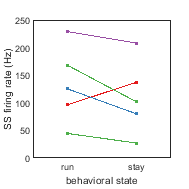

SS_stay_all = zeros(1,length(channels));
SS_run_all = zeros(1,length(channels));
for ii = 1: length(channels)
    PC = load([analysis_dest channels{ii} '.mat']);
    SS_stay = PC.SS_stay;
    SS_run = PC.SS_run;
    SS_stay_all(ii) = SS_stay;
    SS_run_all(ii) = SS_run;
end
SS_states_all = cat(1,SS_run_all,SS_stay_all);

x = [1,2]; x_plot = repmat(x,size(SS_states_all,2),1);
x_plot = x_plot';
SS_states = figure; %make cells from the same session a same color
plot(x_plot(:,1),SS_states_all(:,1),'.','LineStyle','-','linewidth', 0.8,'MarkerSize',6,'color',[0.8941 0.1020 0.1098]);hold on;
plot(x_plot(:,2),SS_states_all(:,2),'.','LineStyle','-','linewidth', 0.8,'MarkerSize',6,'color',[0.2157 0.4941 0.7216]);
plot(x_plot(:,3:4),SS_states_all(:,3:4),'.','LineStyle','-','linewidth', 0.8,'MarkerSize',6,'color',[0.3020 0.6863 0.2902]);
plot(x_plot(:,5),SS_states_all(:,5),'.','LineStyle','-','linewidth', 0.8,'MarkerSize',6,'color',[0.5961 0.3059 0.6392]);
xlabel ('behavioral state');xlim([0.5 2.5]); axis square;
set(gca,'XTick',x,'XTicklabel',{'run','stay'});
ylabel('SS firing rate (Hz)');
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontSize',7);
%title('df/f for each beahvioral state all sessions'); %legend('ROI1','ROI2','ROI3','ROI4','ROI5');

SS_states.Units = 'centimeters';
SS_states.Position = [1 1 5 5];
fig_name = 'SSrate_across_session_stayVsrun';
path = [analysis_dest 'figures\']; 
%orient(dfOvF_behavStates,'landscape');
print(SS_states,[path,fig_name],'-r600','-dpdf');
hold off;

## SSrate aligned to running onset and offset

SStrig_all = zeros(26,length(channels));
SSoff_all = zeros(26,length(channels));
SStrig_all_ste = zeros(26,length(channels));
SSoff_all_ste = zeros(26,length(channels));
for ii = 1:length(channels)
    PC = load([analysis_dest channels{ii} '.mat']);
    SStrig = PC.ave_SStrig;
    SSoff = PC.ave_SSoff;
    ste_SStrig = PC.ste_SStrig;
    ste_SSoff = PC.ste_SSoff;
    SStrig_all(:,ii) = SStrig';
    SSoff_all(:,ii) = SSoff';
    SStrig_all_ste(:,ii) = ste_SStrig';
    SSoff_all_ste(:,ii) = ste_SSoff';
end


runoffSpd_all = zeros(26,length(sessions));
runtrigSpd_all = zeros(26,length(sessions));
runoffSte_all = zeros(26,length(sessions));
runtrigSte_all = zeros(26,length(sessions));
for ii = 1:length(sessions)
    behav_output = load([behav_dest '\' sessions{ii} '_behavAnalysis.mat']);
    runoffSpd = behav_output.ave_speed_runoff;
    runtrigSpd = behav_output.ave_speed_runTrigger;
    runoffSte = behav_output.ste_speed_runoff;
    runtrigSte = behav_output.ste_speed_runTrigger;
    runoffSpd_all(:,ii) = runoffSpd';
    runoffSte_all(:,ii) = runoffSte';
    runtrigSpd_all(:,ii) = runtrigSpd';
    runtrigSte_all(:,ii) = runtrigSte';
end

#### plot

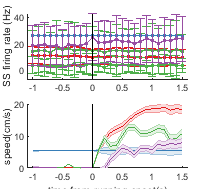


x = ((0:26-1)/10)-1;
SSruntrig_ACS = figure;
subplot(2,1,1);hold on;
errorbar(x,SStrig_all(:,1),SStrig_all_ste(:,1),'.','LineStyle','-','linewidth', 1,'MarkerSize',6,'Color',[0.8941 0.1020 0.1098]);
plot(x,SStrig_all(:,2),'.','LineStyle','-','linewidth', 0.8,'MarkerSize',6,...
    'color',[0.2157 0.4941 0.7216]); % this session only have 2 running trials, ste is super big, so not plotting it here
%errorbar(x,SStrig_all(:,2),SStrig_all_ste(:,2),'.','LineStyle','-','linewidth', 1,'MarkerSize',6,'Color',[0.2157 0.4941 0.7216]);
errorbar([x',x'],SStrig_all(:,3:4),SStrig_all_ste(:,3:4),'.','LineStyle','-','linewidth', 1,'MarkerSize',6,'Color',[0.3020 0.6863 0.2902]);
errorbar(x,SStrig_all(:,5),SStrig_all_ste(:,5),'.','LineStyle','-','linewidth', 1,'MarkerSize',6,'Color',[0.5961 0.3059 0.6392]);

xlim([-1.1 1.6]);
%ylim([0 0.35]);
vline(0,'k');
ylabel('SS firing rate (Hz)'); 
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontSize',7); %with the size of [1 1 5.5 5],font 8 won't plot the whole time scale 

subplot(2,1,2);hold on;
shadedErrorBar(x,runtrigSpd_all(:,1)*2*3.1415926*7.5/128,runtrigSte_all(:,1)*2*3.1415926*7.5/128,...
    {'color',[0.8941 0.1020 0.1098]},{'Linewidth',1});
shadedErrorBar(x,runtrigSpd_all(:,2)*2*3.1415926*7.5/128,runtrigSte_all(:,1)*2*3.1415926*7.5/128,...
    {'color',[0.2157 0.4941 0.7216]},{'Linewidth',1});
shadedErrorBar(x,runtrigSpd_all(:,3)*2*3.1415926*7.5/128,runtrigSte_all(:,1)*2*3.1415926*7.5/128,...
    {'color',[0.3020 0.6863 0.2902]},{'Linewidth',1});
shadedErrorBar(x,runtrigSpd_all(:,4)*2*3.1415926*7.5/128,runtrigSte_all(:,1)*2*3.1415926*7.5/128,...
    {'color',[0.5961 0.3059 0.6392]},{'Linewidth',1});
%'.','LineStyle','-','linewidth', 1.25,'MarkerSize',20); hold on;
xlabel('time from running onset(s)');
ylabel('speed(cm/s)');
ylim([0 20]);
vline(0,'k');
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontSize',7);
xlim([-1.1 1.6]);
SSruntrig_ACS.Units = 'centimeters';
SSruntrig_ACS.Position = [1 1 5.5 5];
fig_name = 'SSrate_runtrig_across';
path = [analysis_dest 'figures\']; 
%orient(dfOvF_behavStates,'landscape');
print(SSruntrig_ACS,[path,fig_name],'-r600','-dpdf');
hold off;

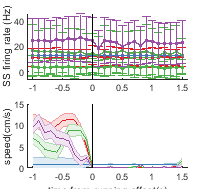


SSrunoff_ACS = figure;
subplot(2,1,1);hold on;
errorbar(x,SSoff_all(:,1),SSoff_all_ste(:,1),'.','LineStyle','-','linewidth', 1,'MarkerSize',6,'Color',[0.8941 0.1020 0.1098]);
plot(x,SSoff_all(:,2),'.','LineStyle','-','linewidth', 0.8,'MarkerSize',6,...
    'color',[0.2157 0.4941 0.7216]); % this session only have 2 running trials, ste is super big, so not plotting it here
%errorbar(x,SSoff_all(:,2),SSoff_all_ste(:,2),'.','LineStyle','-','linewidth', 1,'MarkerSize',6,'Color',[0.2157 0.4941 0.7216]);
errorbar([x',x'],SSoff_all(:,3:4),SSoff_all_ste(:,3:4),'.','LineStyle','-','linewidth', 1,'MarkerSize',6,'Color',[0.3020 0.6863 0.2902]);
errorbar(x,SSoff_all(:,5),SSoff_all_ste(:,5),'.','LineStyle','-','linewidth', 1,'MarkerSize',6,'Color',[0.5961 0.3059 0.6392]);

xlim([-1.1 1.6]);
%ylim([0 0.35]);
vline(0,'k');
ylabel('SS firing rate (Hz)'); 
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontSize',7); %with the size of [1 1 5.5 5],font 8 won't plot the whole time scale 

subplot(2,1,2);hold on;
shadedErrorBar(x,runoffSpd_all(:,1)*2*3.1415926*7.5/128,runoffSte_all(:,1)*2*3.1415926*7.5/128,...
    {'color',[0.8941 0.1020 0.1098]},{'Linewidth',1});
shadedErrorBar(x,runoffSpd_all(:,2)*2*3.1415926*7.5/128,runoffSte_all(:,1)*2*3.1415926*7.5/128,...
    {'color',[0.2157 0.4941 0.7216]},{'Linewidth',1});
shadedErrorBar(x,runoffSpd_all(:,3)*2*3.1415926*7.5/128,runoffSte_all(:,1)*2*3.1415926*7.5/128,...
    {'color',[0.3020 0.6863 0.2902]},{'Linewidth',1});
shadedErrorBar(x,runoffSpd_all(:,4)*2*3.1415926*7.5/128,runoffSte_all(:,1)*2*3.1415926*7.5/128,...
    {'color',[0.5961 0.3059 0.6392]},{'Linewidth',1});
%'.','LineStyle','-','linewidth', 1.25,'MarkerSize',20); hold on;
xlabel('time from running offset(s)');
ylabel('speed(cm/s)');
ylim([0 15]);
vline(0,'k');
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontSize',7);
xlim([-1.1 1.6]);
SSrunoff_ACS.Units = 'centimeters';
SSrunoff_ACS.Position = [1 1 5.5 5];
fig_name = 'SSrate_runoff_across';
path = [analysis_dest 'figures\']; 
%orient(dfOvF_behavStates,'landscape');
print(SSrunoff_ACS,[path,fig_name],'-r600','-dpdf');
hold off;